SFD and BMD

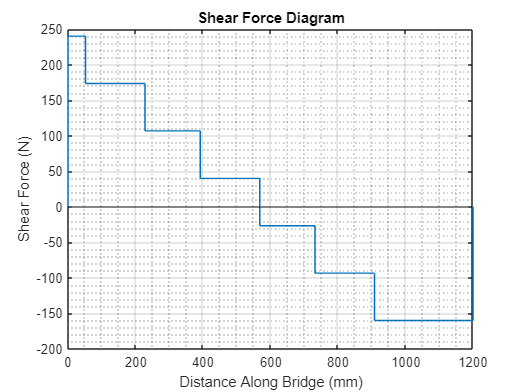

% Design 0

close all;
clear;

x = 0;

y_left = (720-x)/3;
y_right = (x+480)/3;

shear = zeros(1, 16);
shear(1) = 0;
shear(16) = 0;

x_shear = [0, 0, x+52, x+52, x+52+176, x+52+176, x+392, x+392, x+568, x+568, x+732, x+732, x+908, x+908, 1200, 1200];

for i = 1:7
    shear(2*i) = y_left - (200/3)*(i-1);
    shear(2*i+1) = y_left - (200/3)*(i-1);
end
shear;

moment = zeros(1,8);

moment(1) = 0;
moment(8) = 0;

x_moment = [0, x+52, x+52+176, x+392, x+568, x+732, x+908, 1200];


for i = 2:7
    x_val = (x_shear((i-1)*2+1)) - x_shear((i-1)*2-1);
    moment(i) = moment(i-1) + (shear((i-1)*2 + 1) * x_val);
end

moment;

figure
plot(x_shear, shear)
grid on
grid minor
yline(0)
xlabel("Distance Along Bridge (mm)")
ylabel("Shear Force (N)")
title("Shear Force Diagram")

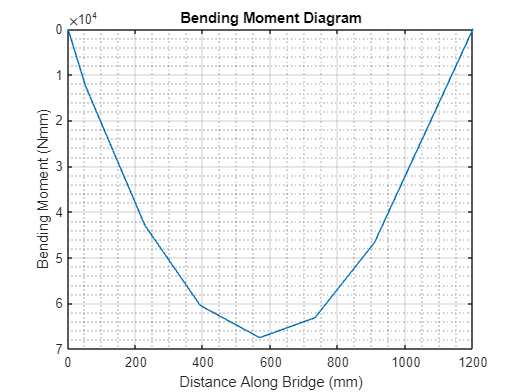


figure
plot(x_moment, moment)
grid on
grid minor
set(gca, 'YDir', 'reverse')  % Flip y-axis
xlabel("Distance Along Bridge (mm)")
ylabel("Bending Moment (Nmm)")
title("Bending Moment Diagram")

Bridge Geometry

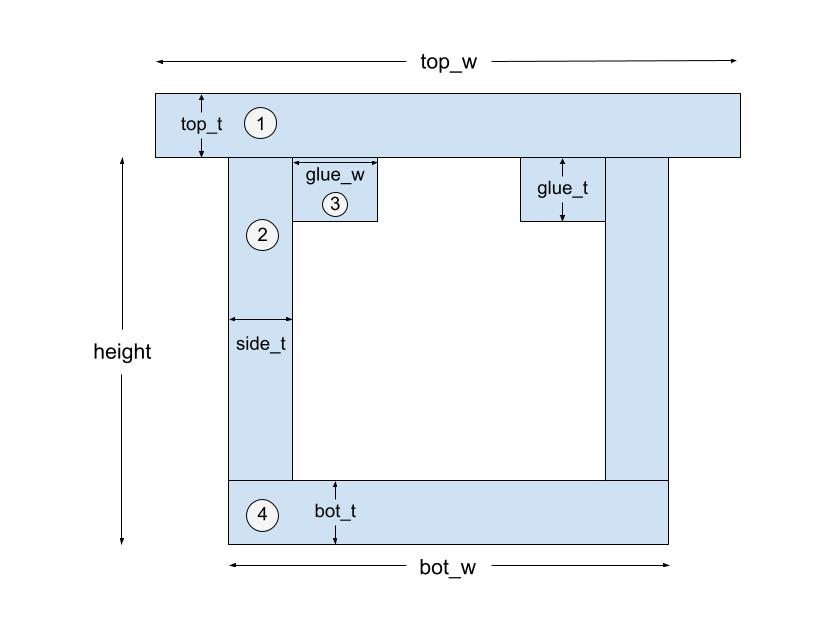

% Define params
top_w = 100;
bot_w = 80;
height = 75; % defined from lowest point without including thickness of the top area
top_t = 1.27;
bot_t = 1.27;
side_t = 1.27;
glue_w = 5; % not including thickness of side
glue_t = 1.27;

Cross-sectional Properties

% Calculate y bar, I, Q_glue, Q_cent
area_1 = top_t * top_w;
area_2 = (height - bot_t)*side_t;
area_3 = glue_w * glue_t;
area_4 = bot_t*bot_w;

y1 = height+top_t/2;
y2 = (height+bot_t)/2;
y3 = height - glue_t/2;
y4 = bot_t/2;

I1 = top_w*(top_t^3)/12;
I2 = side_t*((height-bot_t)^3)/12;
I3 = glue_w*(glue_t^3)/12;
I4 = bot_w*(bot_t^3)/12;

tot_area = area_1 + 2*area_2 + 2*area_3 + area_4;

y_bar = (area_1*y1 + 2*area_2*y2 + 2*area_3*y3 + area_4*y4)/tot_area

y_bar = 41.4311


d1 = y1-y_bar;
d2 = y2-y_bar;
d3 = y3-y_bar;
d4 = y4-y_bar;

sec1 = area_1*(d1^2) + I1;
sec2 = 2*(area_2*(d2^2) + I2);
sec3 = 2*(area_3*(d3^2) + I3);
sec4 = area_4*(d4^2) + I4;

I = sec1+sec2+sec3+sec4

I = 4.1835e+05


Q_cent = (bot_w - 2*side_t)*bot_t*(y_bar - bot_t/2) + 2*y_bar*side_t*y_bar/2

Q_cent = 6.1933e+03

Q_glue = area_1 * (height-y_bar + 1.27/2)

Q_glue = 4.3439e+03

% Daphne

Stresses

% sigma top + bottom, sigma buck tau max tau glue tau buck

% Amin

Thin Plate

% Kevin

